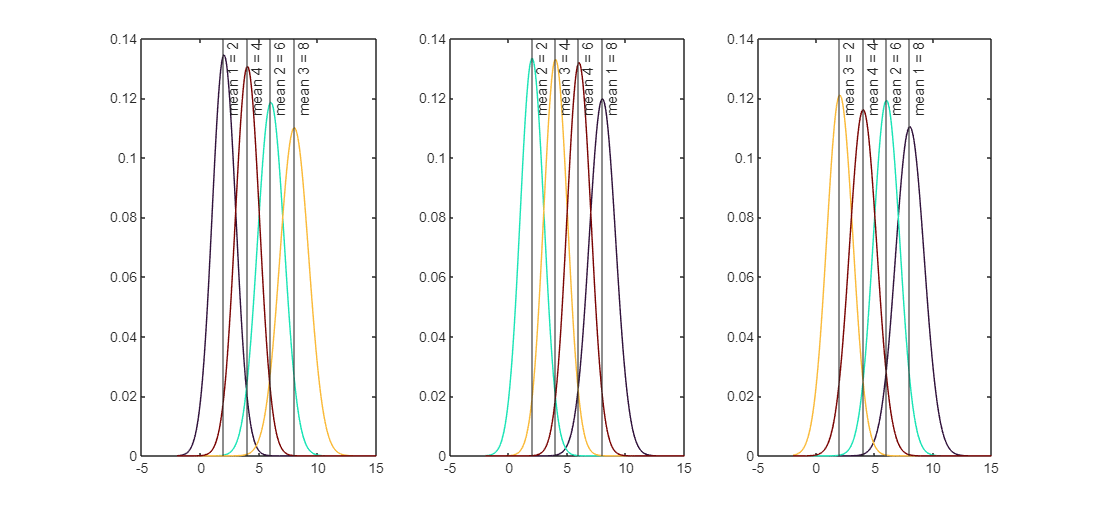

addpath(genpath('HMMUtils/HMM-MAR-master'))


k = 4;
d = 50;
n = 3;
m = 1e4;
normalizeData = false;

hmm_options.method = "random";
hmm_options.epsilon = 1/10;
hmm_options.distribution = 'Normal';

[T, O, pi, ~, ~] = generateContinuousHMM(k, d, n, hmm_options);

cmap = turbo(k);


t = -2:0.01:15;
bin_edges = linspace(t(1), t(end), d+1);
bin_centers = (bin_edges(1:end-1) + bin_edges(2:end)) / 2;

O_hists = pdf2pmf(O, bin_centers);


range = t(end) - t(1);

figure('Renderer', 'painters', 'Position', [10 10 1500 700])
for i = 1:n
    subplot(1, n, i);
    O_hist = O_hists{i};

    for j = 1:k
        y = pdf(O{i,j}, t) * range / d;
        plot(t, y, Color=cmap(j,:)); hold on
        xline(O{i,j}.mean, '-',{"mean " + num2str(j) + " = " + num2str(O{i,j}.mean)}); hold on

        % bar(bin_centers, O_hist(:, j),'FaceAlpha', 0.3, 'EdgeColor', 'none', FaceColor=cmap(j, :)); hold on
    end
end
hold off;

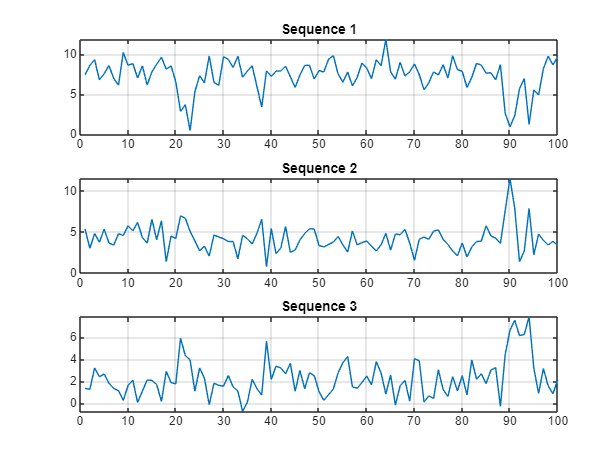



seq = generate_continuous_multivariate_hmm_sequence(T, O, pi, m, 0);


figure();
s = 100;
for i = 1:n
    subplot(n, 1, i);  % Reserve one extra row for the legend
    tempseq = seq(i, :);
    plot(1:s, tempseq(1:s), '-'); hold on;
    title(['Sequence '  num2str(i)]);
    grid on;
end

if(normalizeData)
    for i = 1:n
        tempsec = seq(i, :);
        minSeq = min(tempsec);
        maxSeq = max(tempsec);
        seq(i, :) = (tempsec - minSeq) / (minSeq - maxSeq);
    end
end


[Mu,Cov,A,Pi]=BaumWelch(seq',k);

T_hat = Stochasticize(A);

Pbest = PermutationFit(T, T_hat, true);
T_hat = Pbest * T_hat * Pbest';
Mu = Pbest * Mu;
Cov = tensorprod(Cov, Pbest, 3, 2);

norm(T-T_hat, 'fro')

ans = 0.5103

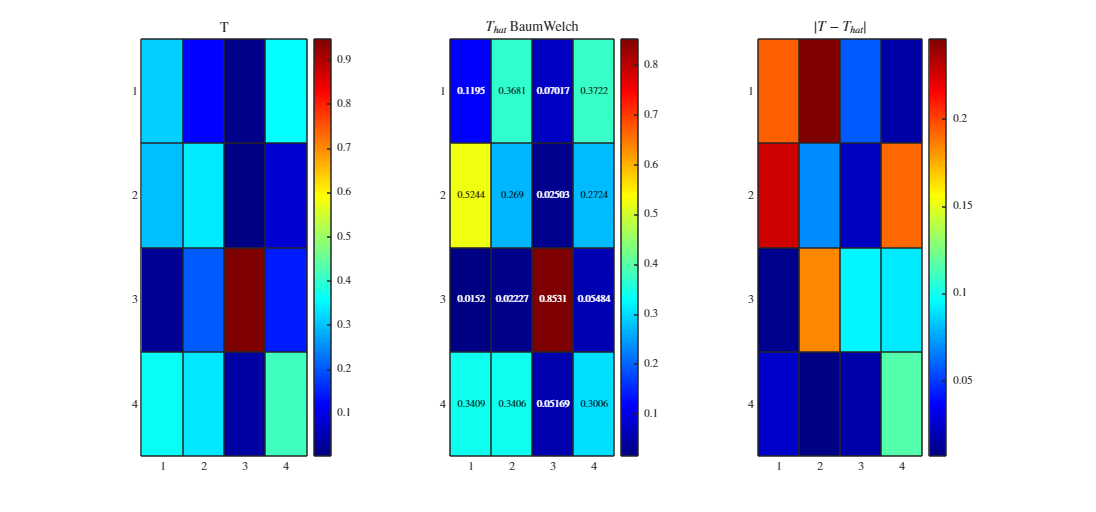


figure('Renderer', 'painters', 'Position', [10 10 1500 700])
subplot(1, 3, 1)
h = heatmap(T, Colormap=jet());
h.Title = 'T';
h.Interpreter = 'latex';

subplot(1, 3, 2)
h = heatmap(T_hat, Colormap=jet());
h.Title = '$T_{hat}$  BaumWelch';
h.Interpreter = 'latex';

subplot(1, 3, 3)
h = heatmap(abs(T-T_hat), Colormap=jet());
h.Title = '$|T-T_{hat}|$';
h.Interpreter = 'latex';

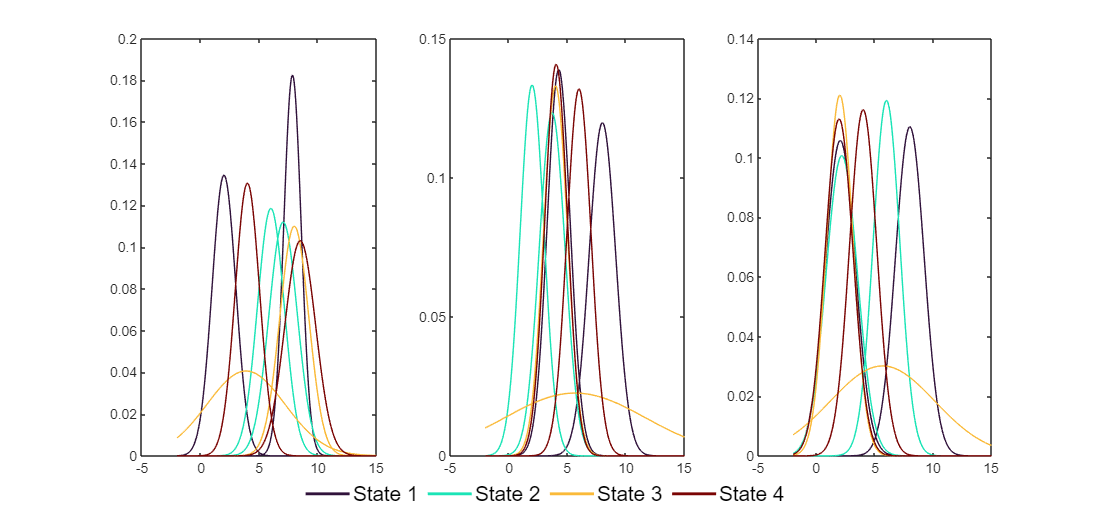


% t = linspace(-10, 10, 1000);

figure('Renderer', 'painters', 'Position', [10 10 1500 700])

for i = 1:n
    subplot(1, n, i);

    for j = 1:k
        mu = Mu(j, i);
        sigma = Cov(i, i, j);

        pd = makedist('Normal', 'mu', mu, 'sigma', sigma);
        plot(t, pdf(pd, t) * range / d, Color=cmap(j,:));
        hold on;

        y = pdf(O{i,j}, t) * range / d;
        plot(t, y, Color=cmap(j,:)); hold on
    end
    hold off;
end

% Add global legend for state colors (dummy axes approach)
% Create invisible axes
ax_dummy = axes('Position', [0 0 1 1], 'Visible', 'off');

% Create dummy lines for legend handles
hold(ax_dummy, 'on');
legend_handles = gobjects(k,1);
for j = 1:k
    legend_handles(j) = plot(ax_dummy, nan, nan, '-', 'Color', cmap(j,:), 'LineWidth', 2);
end

% Create the legend and place it manually below tiledlayout
state_legend = legend(ax_dummy, legend_handles, compose('State %d', 1:k), ...
    'Orientation', 'horizontal', ...
    'Box', 'off', ...
    'FontSize', 14, ...
    'Position', [0.35 0.01 0.3 0.05]);  % Adjust as needed


[~, mins, maxs] = NormalizeData(seq);

[T_hat, O_hats] = Discretize_cHMM_BW(T_hat, Mu, Cov, mins, maxs, d);

Pbest = MultivariatePermutationFitEmission(O_hists, O_hats);

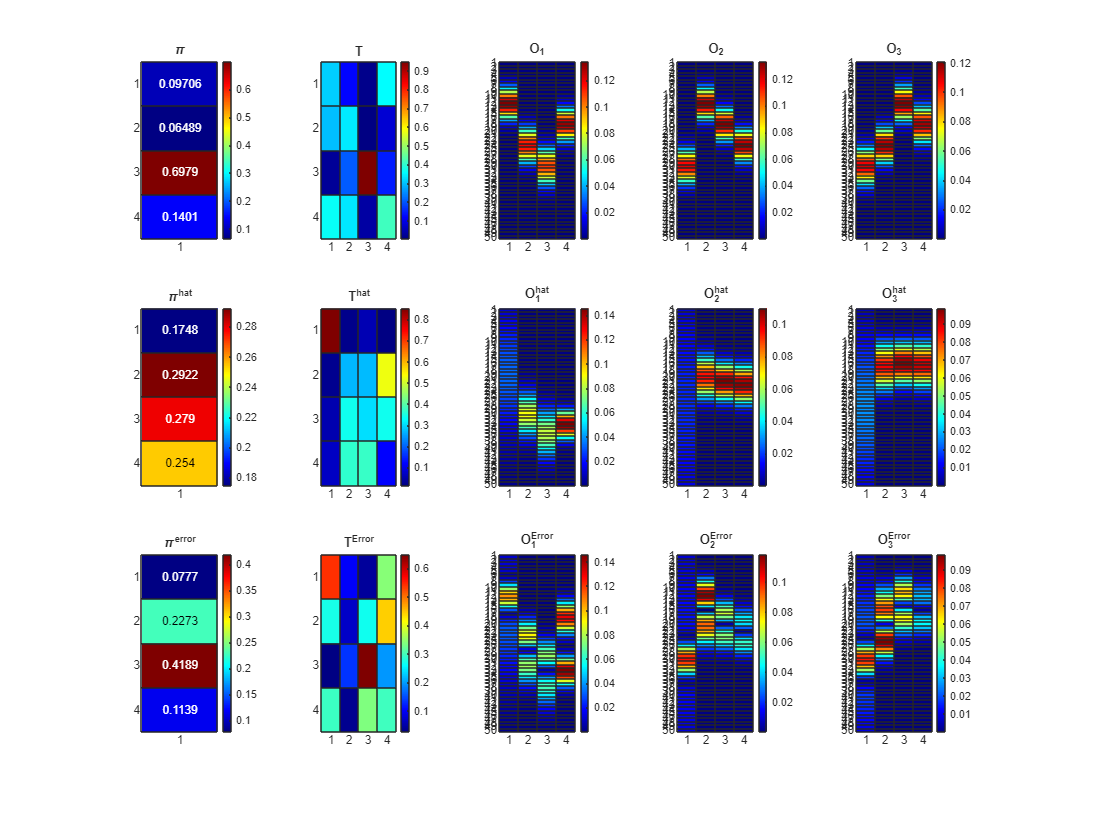


T_hat = Pbest * T_hat * Pbest';

for i = 1:n
    O_hats{i} = O_hats{i} * Pbest';
end

plotHMMError(T, O_hists, T_hat, O_hats)